Геометрические параметры

clear all;
a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;

K = 0;
T_a = 1;
theta_2 = linspace(0, pi/3, 100);

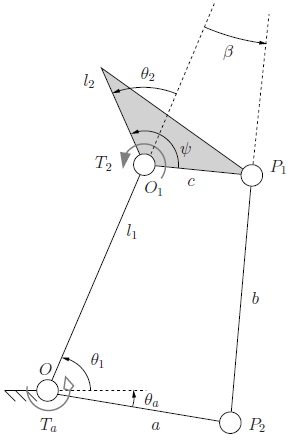

Определение контактных сил в зависимости от конфигурации

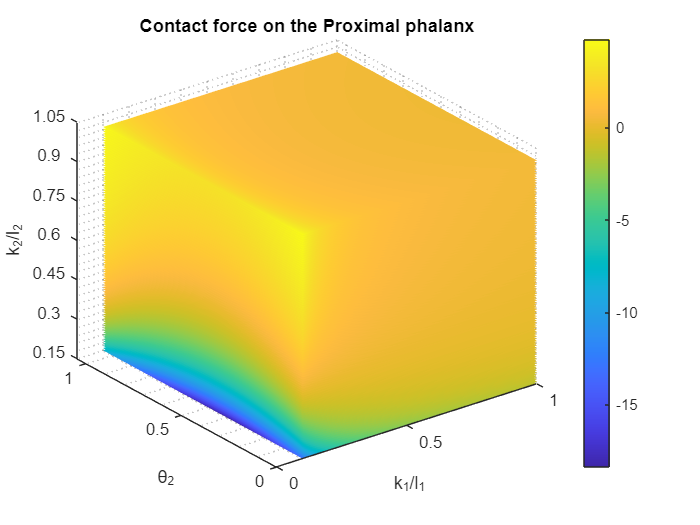

x = linspace(0.1, l_1, size(theta_2,2));
y = theta_2;
z = linspace(0.1, l_2, size(theta_2,2));


[X,Y,Z] = ndgrid(x,y,z);
[F_1, F_2] = contactForces(a,b,c,l_1,psi,K,T_a,X,Y,Z);

f1 = figure;
f2 = figure;

figure(f1);
hold on;
for i = 1:size(x,2)
    surf(X(:,:,i),Y(:,:,i),Z(:,:,i),F_1(:,:,i)) ;
end
grid minor;
view(3);
shading interp
title('Contact force on the Proximal phalanx');
xlabel('k_1/l_1');
ylabel('\theta_2');
zlabel('k_2/l_2');
colorbar;
ax=gca;
ax.XTickLabel= ax.XTick/l_1;
ax.ZTickLabel= ax.ZTick/l_2;

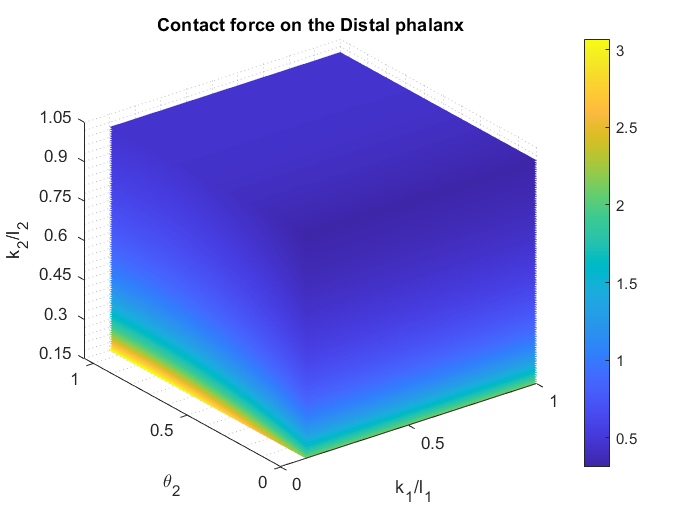


figure(f2);
hold on
for i = 1:size(x,2)
    surf(X(:,:,i),Y(:,:,i),Z(:,:,i),F_2(:,:,i)) ;
end
grid minor;
view(3);
shading interp
title('Contact force on the Distal phalanx');
xlabel('k_1/l_1');
ylabel('\theta_2');
zlabel('k_2/l_2');
colorbar;
ax=gca;
ax.XTickLabel = ax.XTick/l_1;
ax.ZTickLabel = ax.ZTick/l_2;

Поиск конфигураций, соответствующих f_1 = f_2

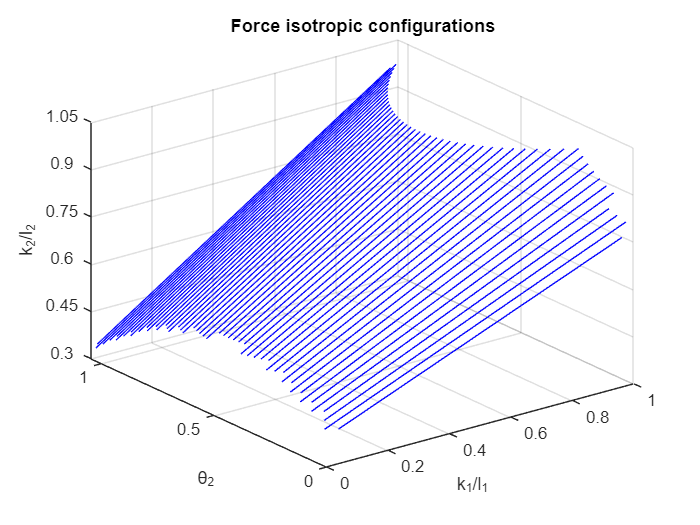

clear all;
syms k_2 k_1 theta_2;
a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;

K = 0;
T_a = 1;
theta_2 = linspace(0, pi/3, 50);

f3 = figure;
figure(f3);
for i = theta_2
    syms k_2 k_1;
    [F_1, F_2] = contactForces(a, b, c, l_1, psi, K, T_a, k_1, i, k_2);
    
    k_2 = linspace(0.1, l_2, 50);
    [sol_1, parameters, conditions] = solve(F_1==F_2, k_1,'ReturnConditions',true);
    k_1 = subs(sol_1);
    
    L1 = vpa(conditions);
    L2 = k_1 > 0;
    L3 = k_1 < l_1;
    L4 = k_2 > 0;
    L5 = k_2 < l_2;

    L = logical(L1 & L2 & L3 & L4 & L5);
    
    k_1 = double(k_1(L));
    k_2 = double(k_2(L));
    thet2 = i*ones(1, size(k_2, 2));
    plot3(k_1, thet2, k_2, '-b');    
    hold on;
end

grid on;
title('Force isotropic configurations');
xlabel('k_1/l_1');
ylabel('\theta_2');
zlabel('k_2/l_2');

ax=gca;
ax.XTickLabel = ax.XTick/l_1;
ax.ZTickLabel = ax.ZTick/l_2;

Поиск и визуализация устойчивых конфигураций захвата

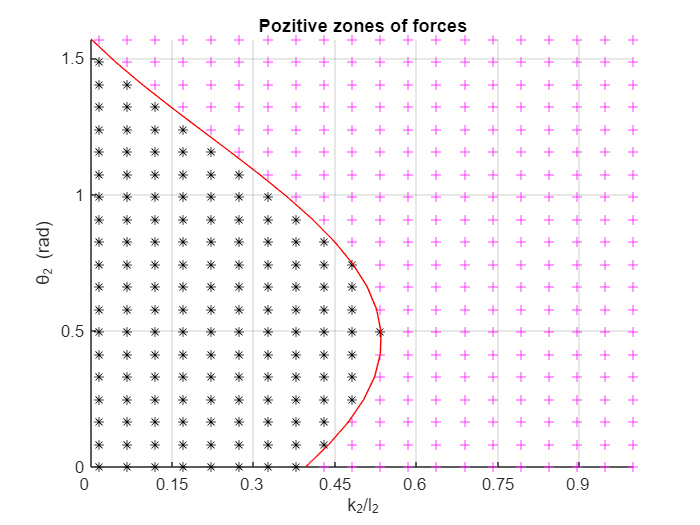

clear all;

a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;
K = 0;
T_a = 1;
k_1 = 1;
theta_2 = linspace(0, pi/2, 20);

k_2 = linspace(0.01, l_2, 20);

f4 = figure;
hold on;
ii = 1;
jj = 1;
for i = theta_2
    for j = k_2
        [f_1, f_2] = contactForces(a, b, c, l_1, psi, K, T_a, k_1, i, j);
        f_1 = double(subs(f_1));
        f_2 = double(subs(f_2));
        L1 = f_1 >= 0;
        L2 = f_2 >= 0;
        L = L1 & L2;

        figure(f4);
        if (L)
            % Визуализация зоны устойчивого захвата
            plot(j, i, 'Marker','+','Color','m');
            k_2pos(ii) = j;
            angPos(ii) = i;
            ii = ii + 1;
        else
            % % Визуализация зоны неустойчивого захвата
            plot(j, i, 'Marker','*','Color','k');
            k_2neg(jj) = j;
            angNeg(jj) = i;
            jj = jj + 1;
        end
    end
end
    
% График траектории для f_1 = 0 - граница раздела между устойчивой
% зоной и неустойчивой: k2 = h*cos(thetf_2)
k_2 = h(a, b, c, l_1, psi, theta_2).*cos(theta_2);
plot(k_2,theta_2, 'LineStyle','-','Color','r');

grid on;
title('Pozitive zones of forces');
xlabel('k_2/l_2');
ylabel('\theta_2 (rad)');

axis([0 max(l_2) 0 max(theta_2)]);
ax=gca;
ax.XTickLabel = ax.XTick/l_2;

Построение траекторий контакта при контакте дистальной фалангой

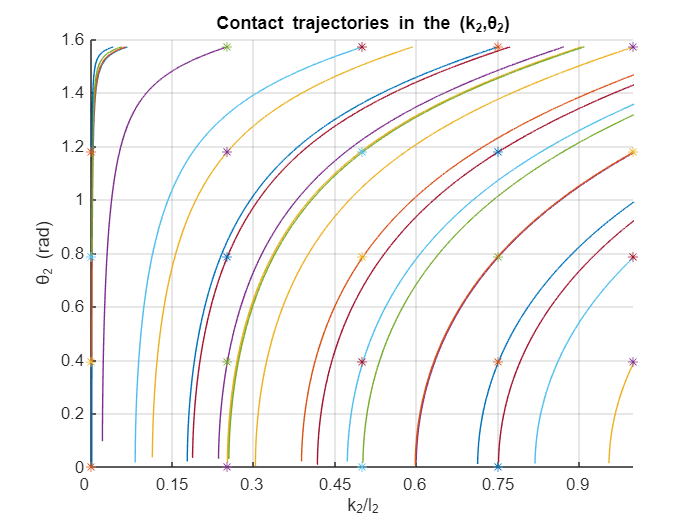

clear all;
l_1 = 1; l_2 = 2/3;

syms k_2 k_2i theta_2 theta_2i;

f = contactRestriction(k_2,theta_2,k_2i,theta_2i, l_1);
theta_2 = solve(f==0, theta_2);

f5 = figure;
hold on;
f6 = figure;
hold on;

theta_2i = linspace(0, pi/2, 5);
k_2i = linspace(0.001, l_2, 5);
[X, Y] = ndgrid(k_2i, theta_2i);
k_2i = X; theta_2i = Y;



for i = 1:(size(X,1)*size(X,2))
    k_2i = X(i); theta_2i = Y(i);

    % acos дает два решения. Берем второе, соответствующее angle = +acos(...)
    theta_22 = subs(theta_2(2,:));

    k_2 = linspace(0.001, l_2, 5000);
    ang = double(subs(theta_22));

    k = 1;
    flag = 0;
    for j = 1:size(ang,2)
        if isreal(ang(j)) && ang(j) >= 0 && ang(j) <= pi/2
            k_22(k) = k_2(j);
            ang_22(k) = ang(j);  
            cos_ang_22(k) = cos(ang(j));
            flag = 1;

            k = k + 1;
        end
    end         
    
    % Проверка, что для выбранных н.у. существует траектория контакта 
    if flag && (size(k_22,2) > 1)
        figure(f5);    
        plot(k_22, ang_22);
        plot(k_2i, theta_2i, 'Marker','*');
        
        figure(f6);
        hold on;
        plot(k_22, cos_ang_22);
        plot(k_2i, cos(theta_2i), 'Marker','*');
    end
    clear k_22 ang_22 cos_ang_22;
end

figure(f5);
grid on;
title('Contact trajectories in the (k_2,\theta_2)');
xlabel('k_2/l_2');
ylabel('\theta_2 (rad)');
xlim([0 l_2]);
ax=gca;
ax.XTickLabel = ax.XTick/l_2;

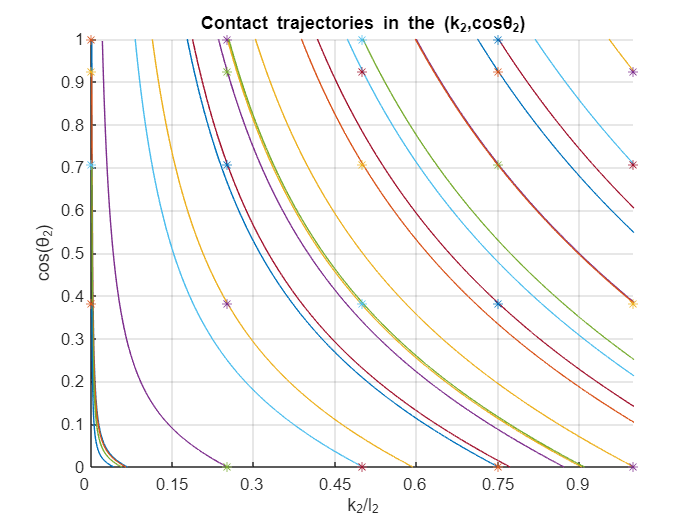


figure(f6);
grid on;
title('Contact trajectories in the (k_2,cos\theta_2)');
xlabel('k_2/l_2');
ylabel('cos(\theta_2)');
ax=gca;
ax.XTickLabel = ax.XTick/l_2;
xlim([0 l_2]);
ylim([0 1]);